# MATLAB做增强现实AR

同济子豪兄 https://space.bilibili.com/1900783

2021-08-04

clear
clear global
% 指定全局变量
global camera A C alphaBlender pointTracker outputView_A outputView_B scaleTransform

% 初始化摄像头
camera = webcam(char(webcamlist));
% 等待一小段时间
pause(0.5);
% 先拍一张，但摄像头刚打开拍摄画面会比较黑暗
B = snapshot(camera);
% 等待一小段时间
pause(0.5);
% 再拍一张，画面就正常了
B = snapshot(camera);

% 初始化点追踪器
pointTracker = vision.PointTracker('MaxBidirectionalError',2);

% 单独新建一个窗口产生可视化结果
set(gcf,'Visible','on');

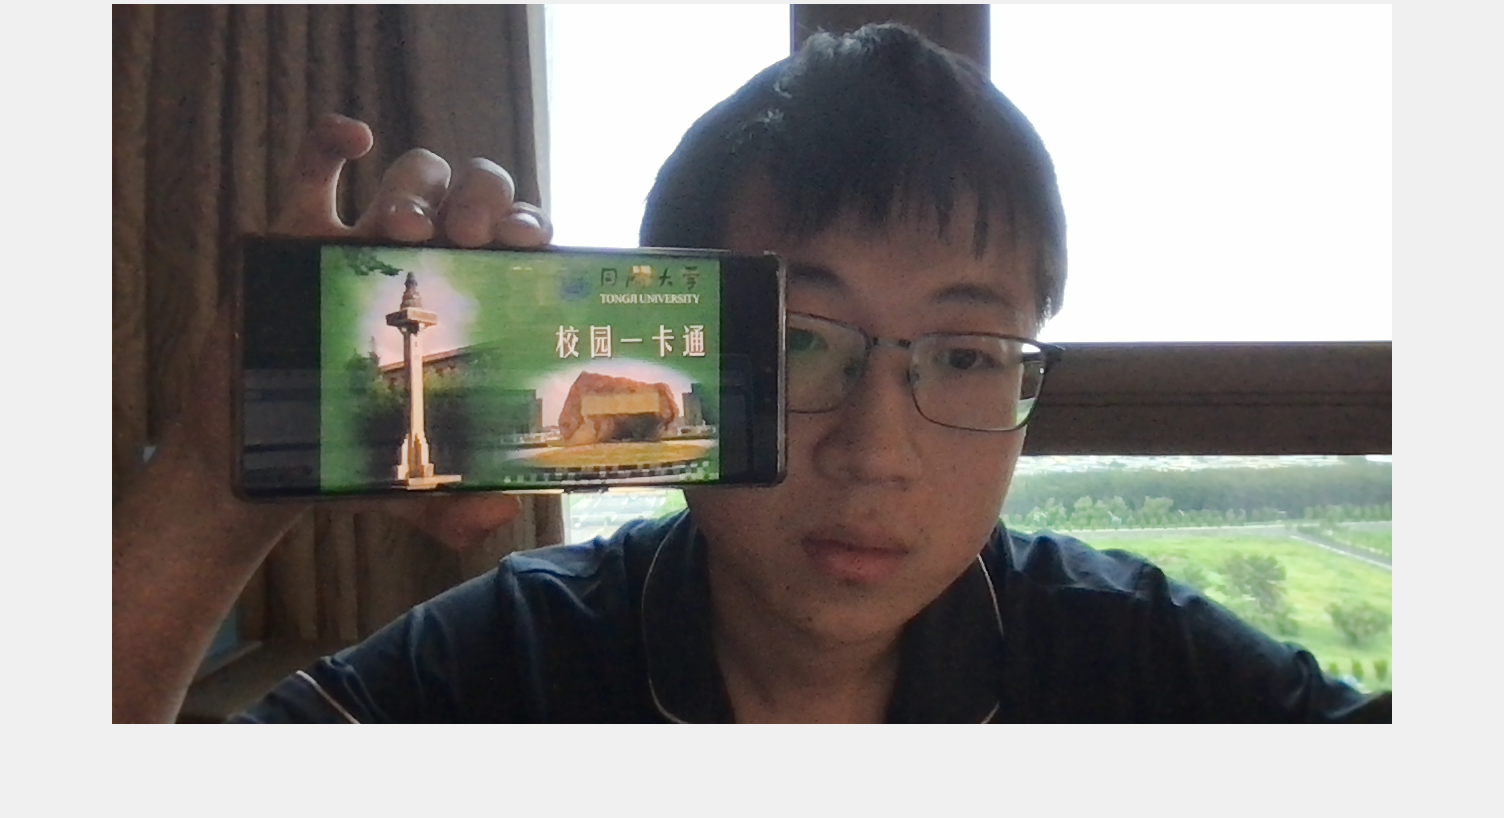

imshow(B);

A = imread('A.png');
C = imread('C.jpg');

% A图，转灰度图，提取特征
AGray = rgb2gray(A);
APts = detectSURFFeatures(AGray);
AFeatures = extractFeatures(AGray, APts);

alphaBlender = vision.AlphaBlender('Operation','Binary mask','MaskSource','Input port');

outputView_A = imref2d(size(A));
outputView_B = imref2d(size(B));

% C图
% 先将C图缩放至与A图相同大小
% 获取C图size
CDims = size(C(:,:,1));
% 获取A图size
ADims = size(A);

% find transformation that scales video frame to replacement iamge size
% preserving aspect ratio
scaleTransform = findScaleTransform(ADims, CDims);

## 处理初始帧

[inlierBPts, referenceTransform] = process_frame(A, AFeatures, APts, B, C);

## 连续调用摄像头，拍摄实时画面

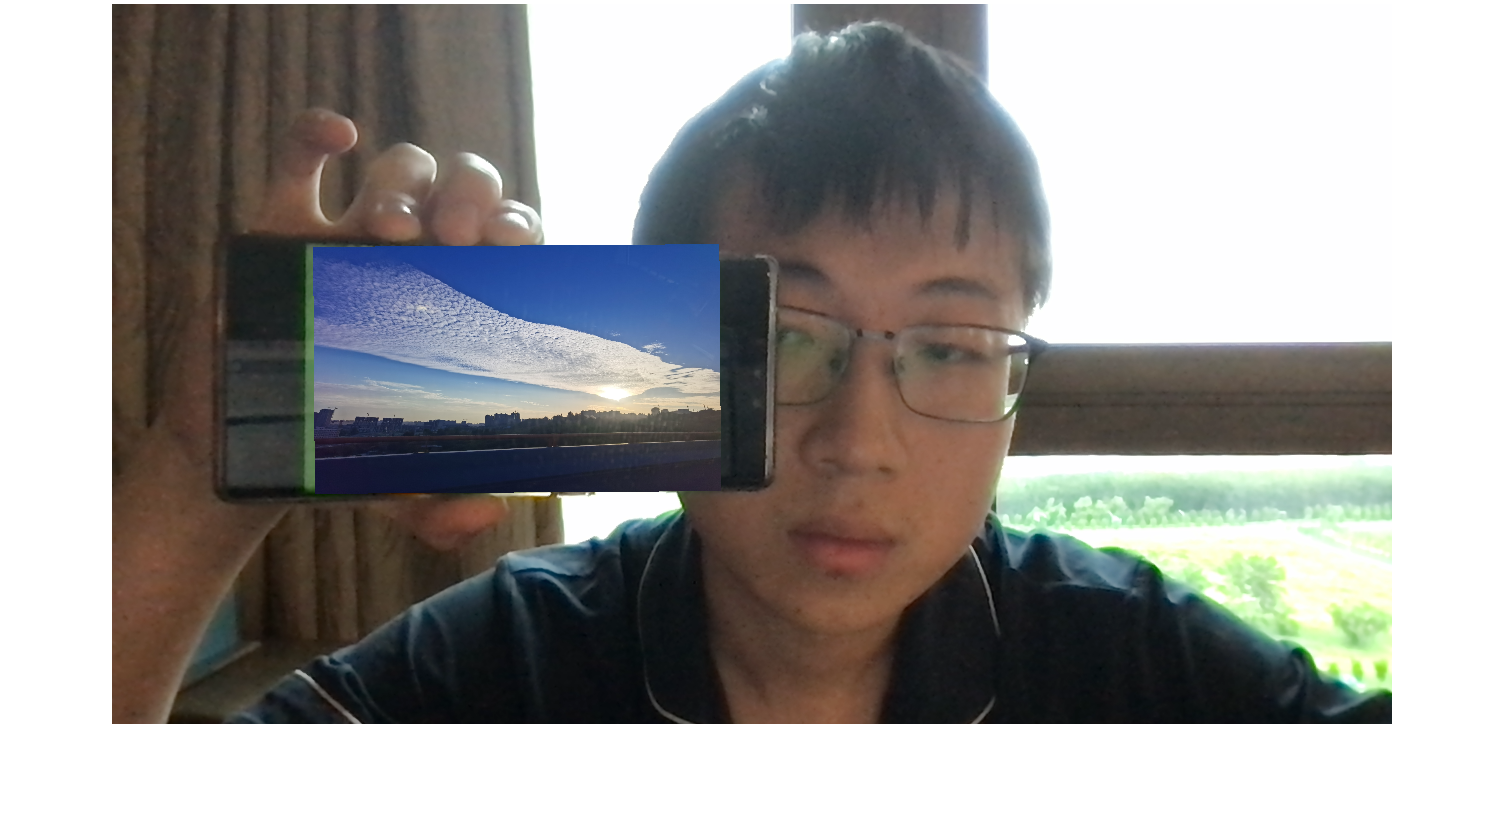

for idx = 1:1000
    
    [outputFrame, B] = process_tracking(B, inlierBPts, referenceTransform);
    [inlierBPts, referenceTransform] = process_frame(A, AFeatures, APts, B, C);
   
    imshow(outputFrame);
    
   % 调用摄像头拍摄一帧画面作为B图像
   % B = snapshot(camera);
   
   % 调用process_frame函数，输入ABC三张图像，输出中间结果和最终结果
   % [matchedBPts, matchedAPts, CScaled, CTransformed, outputFrame] = process_frame(A, B, C);

   % 展示结果
   % imshow(B);
   % showMatchedFeatures(B, A, matchedBPts, matchedAPts, 'Montage');
   % imshow(CScaled);
   % imshow(CTransformed);
end


% 关闭摄像头
delete(camera);

## 定义函数findScaleTransform

function [scaleTransform ]=  findScaleTransform(refDims,repDims)
if (repDims(1)/repDims(2) > 1) && (refDims(2)/refDims(2) > 1) % 当两张图片长宽比相同时
    scaleTransform=affine2d([1/(repDims(1)/refDims(1)) 0 0 ; 0 1/(repDims(2)/refDims(2)) 0 ;0 0 1]);
else % 当两张图片长宽比不同时
    scaleTransform=affine2d([0 1/(repDims(2)/refDims(1))  0 ;  1/(repDims(1)/refDims(2)) 0 0 ;0 0 1]);
end
end

## 定义process_frame函数，输入ABC三张图像，输出中间结果和最终结果

function [inlierBPts, referenceTransform] = process_frame(A, AFeatures, APts, B, C)
global alphaBlender outputView_A outputView_B scaleTransform

% B图，转灰度图，提取特征
BGray = rgb2gray(B);
BPts = detectSURFFeatures(BGray);
BFeatures = extractFeatures(BGray, BPts);

% 两张图像的SURF特征匹配
idxPairs = matchFeatures(BFeatures, AFeatures);
% 分别取出匹配特征的第一列和第二列，可视化特征匹配结果
% 第一列对应B图的特征点位置
matchedBPts = BPts(idxPairs(:,1));
% 第二列对应A图的特征点位置
matchedAPts = APts(idxPairs(:,2));

% 计算A图和B图的几何变换关系
[referenceTransform, inlierAPts, inlierBPts] = estimateGeometricTransform(matchedAPts, matchedBPts, 'Similarity');

% C图
% 先将C图缩放至与A图相同大小
% 获取C图size
% CDims = size(C(:,:,1));
% 获取A图size
% ADims = size(A);

% find transformation that scales video frame to replacement iamge size
% preserving aspect ratio
% scaleTransform = findScaleTransform(ADims, CDims);
% CScaled = imwarp(C, scaleTransform, 'OutputView', outputView_A);

% 再将C图缩放至B图的校园卡对应区域
% CTransformed = imwarp(CScaled, referenceTransform, 'OutputView', outputView_B);

% 将B图的校园卡区域替换成C图
% alphaBlender = vision.AlphaBlender('Operation','Binary mask','MaskSource','Input port');
% 选出CTransformed有图像的区域
% mask = CTransformed(:,:,1) | CTransformed(:,:,2) | CTransformed(:,:,3) > 0;
% outputFrame = step(alphaBlender, B, CTransformed, mask);

end

## 定义process_tracking函数，输入当前帧，拍摄下一帧，并返回追踪效果和下一帧

function [outputFrame, B] = process_tracking(B, inlierBPts, referenceTransform)
global camera pointTracker A C alphaBlender outputView_A outputView_B scaleTransform

initialize(pointTracker, inlierBPts.Location, B);
% 展示用于追踪的点
% trackingMarkers = insertMarker(B, inlierBPts.Location, 'x', 'Size', 10, 'Color', 'red');
% imshow(trackingMarkers);

% 存储当前帧摄像头拍摄到的画面
prevCameraFrame = B;
% 摄像头拍摄下一帧画面
B = snapshot(camera);

% 在下一帧画面中找到追踪点
[trackedPoints, isValid] = step(pointTracker, B);

% 前后两帧画面的高置信度对应追踪点 个数 超过2时
if (nnz(isValid) >=2)
    % 只选取两帧画面中的高置信度追踪点
    newValidLocations = trackedPoints(isValid,:);
    oldValidLocations = inlierBPts.Location(isValid,:);
    
    [trackingTransform, oldInlierLocations, newInlierLocations] = estimateGeometricTransform(oldValidLocations, newValidLocations, 'Similarity');
    % 展示上下两帧画面的高置信度对应追踪点
    % showMatchedFeatures(prevCameraFrame, B, oldInlierLocations, newInlierLocations, 'Montage');
    
    % 重启下一帧的点追踪
    setPoints(pointTracker, newValidLocations);
    % accumulate geometric transformations from reference to current Frame
    trackingTransform.T = referenceTransform.T * trackingTransform.T;
    % rescale new replacement video frame
    CScaled = imwarp(C, scaleTransform, 'OutputView', outputView_A);
    % apply total geometric transformation to new replacement video frame
    CTransformed = imwarp(CScaled, trackingTransform, 'OutputView', outputView_B);
    % 选出CTransformed有图像的区域
    mask = CTransformed(:,:,1) | CTransformed(:,:,2) | CTransformed(:,:,3) > 0;
    outputFrame = step(alphaBlender, B, CTransformed, mask);
else
    outputFrame = B;
end

release(pointTracker);

end
